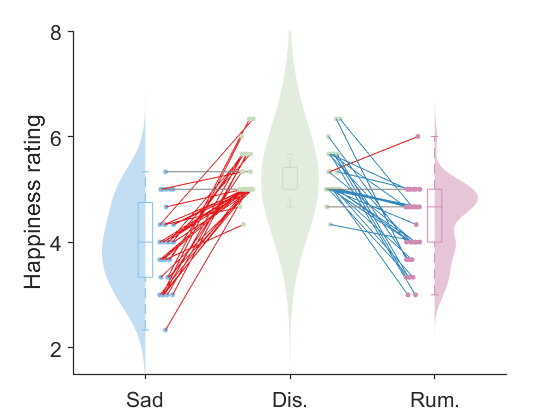

clear, clc
close all
datadir = 'G:\A_arousal_analysis\data';
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
cols1 = cols1./255;

% ratings from https://github.com/Chaogan-Yan/PaperScripts/blob/master/Chen_2020_NeuroImage/scripts/Questionnaire_stats.m
load(fullfile(datadir, 'IPCAS_QuestionnaireData.mat'))
emotion = cell2mat(EmotionScore);
emotion(:,3) = emotion(:,4);
emotion(:,4) = emotion(:,5);
emotion(:,5) = emotion(:,6);
emotion(:,6) = [];
% we focus on sad, rumination and distraction
emotion = emotion(:, 3:5);
emotion_IPCAS = emotion(:);

load(fullfile(datadir, 'PKUGE_QuestionnaireData.mat'))
emotion = cell2mat(EmotionScore);
emotion(:,3) = emotion(:,4);
emotion(:,4) = emotion(:,5);
emotion(:,5) = emotion(:,6);
emotion(:,6) = [];
emotion = emotion(:, 3:5);
emotion_PKUGE = emotion(:);

load(fullfile(datadir, 'PKUSIEMENS_QuestionnaireData.mat'))
emotion = cell2mat(EmotionScore);
emotion(:,3) = emotion(:,4);
emotion(:,4) = emotion(:,5);
emotion(:,5) = emotion(:,6);
emotion(:,6) = [];
emotion = emotion(:, 3:5);
emotion_PKUSIEMENS = emotion(:);

emotion = (emotion_IPCAS + emotion_PKUGE + emotion_PKUSIEMENS)/3;

dataConditions = {emotion(1:41), emotion(83:end), emotion(42:82)};
conditionLabels = {'Sad', 'Dis.', 'Rum.'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
lefthigher = dataConditions{1} > dataConditions{2};
linecolors{1}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
equals = dataConditions{1} == dataConditions{2};
linecolors{1}(equals, :) = repmat([0.5 0.5 0.5], sum(equals), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
lefthigher = dataConditions{2} > dataConditions{3};
linecolors{2}(lefthigher, :) = repmat([0.1961    0.5333    0.7412], sum(lefthigher), 1);
equals = dataConditions{2} == dataConditions{3};
linecolors{2}(equals, :) = repmat([0.5 0.5 0.5], sum(equals), 1);


plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols1([4,8,9],:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('Happiness rating');
set(gca,'YLim', [1.5 8], 'ytick',2:2:8, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',16, 'LineWidth', 1)


% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 6.5 5.5]);
% print('-dtiff', 'A_positive_rating_study3.tif', '-r400')
% 
% close all